# 'grid' method usage example

Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'grid.pov', 'image_file', 'grid.png');

    % Camera
    pl.camera('angle', 50, 'location', [-22 -22 8], 'look_at', [-6 -6 -4], 'type', 'perspective');

    % Lights
    pl.light('location', [-20 -20 8], 'color', [0.4 0.4 0.4], 'shadowless', true);
    pl.light('location', [-20 20 8],  'color', [0.1 0.1 0.1]);
    
    % Textures
    tex_floor  = pl.declare("tex_floor", pl.texture('pigment', [0.02 0.02 0.02]));
    tex_pink   = pl.declare("tex_pink",   pl.texture('pigment', [8 2 3]));
    tex_green  = pl.declare("tex_green",  pl.texture('pigment', [0 8 0]));
    tex_yellow = pl.declare("tex_yellow", pl.texture('pigment', [8 8 0]));
    tex_blue   = pl.declare("tex_blue",   pl.texture('pigment', [2 4 8]));
    
    % Floor
    pl.plane('normal', [0,0,1], 'texture', tex_floor, 'translate', [0 0 -0.07]);
    
    % Objects
    pl.grid('cell_size', 1,'width', 5, 'height', 5, 'radius', 0.04, 'texture', tex_pink,   'rotate', [ 90 0 0], 'translate', [-8 -8 0]);
    pl.grid('cell_size', 1,'width', 5, 'height', 5, 'radius', 0.04, 'texture', tex_yellow, 'rotate', [ 90 0 0], 'translate', [-13.2 -8 0]);
    pl.grid('cell_size', 1,'width', 5, 'height', 5, 'radius', 0.04, 'texture', tex_green,  'rotate', [ 90 0 0], 'translate', [-8 -13.2 0]);
    pl.grid('cell_size', 1,'width', 5, 'height', 5, 'radius', 0.04, 'texture', tex_blue,   'rotate', [ 90 0 0], 'translate', [-13.2 -13.2 0]); 

pl.scene_end();

#### Render and display

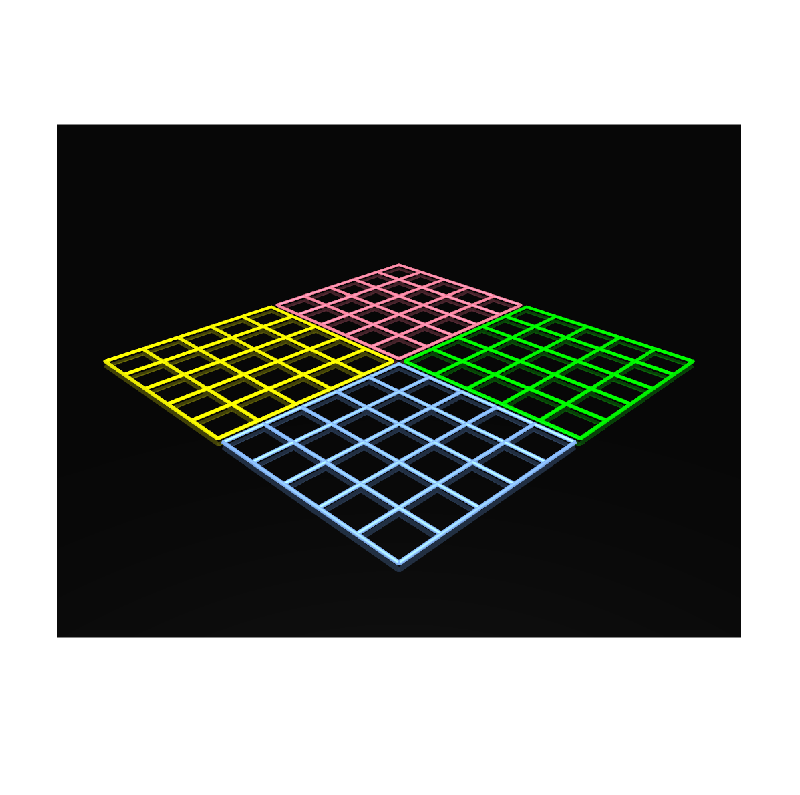

image = pl.render();
imshow(image);

#### Display elapsed time

toc

Elapsed time is 3.438127 seconds.
